# PyDES - A Performance Modeling Showcase

Giacomo Marciani

Department of Civil and Computer Engineering

University of Rome Tor Vergata

[gmarciani@acm.org](mailto:gmarciani@acm.org)

## `Abstract`

`This script visualizes the performance evaluation of the system proposed in [1]. The dataset is generated by the experiements implememted in [2].`

`This script allows to conduct the following studies:`

- `randomness``: the custom pseudo-random number generator is evaliuated in comparison with a past e present de-facto standard;`

- `transient analysis``: the transient period of the proposed system is evaluated taking into account the convergence of response time, throughput and mean population;`

- `performance evaluation``: the performance metrics of the proposed system are evaluated. In particular we assess response time, throughput, mean population, switched ratio and switched response time both classed/global and system/subsystems.`

`This work is inteded as a final test for the course in Performance Modeling of Computer Systems and Networks[7,8,9].`

## `Pseudo-Random Number Generation`

`Let us evaluate the pseudo-random number generator, defined by the following parameters, assessing its randomness with the Spectral Test[4], the Test of Extremes[4] and the Kolmogorov-Smirnov Analysis[4].`

modulus = 2147483647;
multipliers = [50812, 48271, 16807];

`Spectral Test`

`Let us see the results obtained with the Spectral Test.`

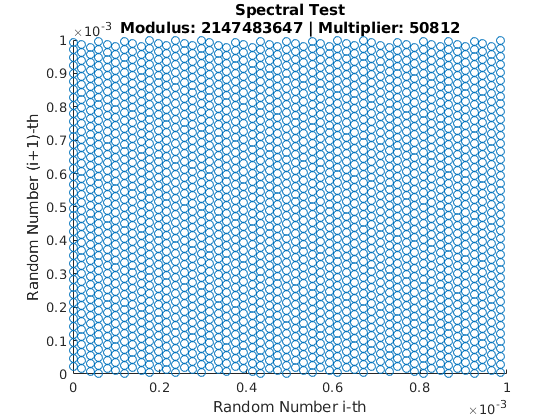

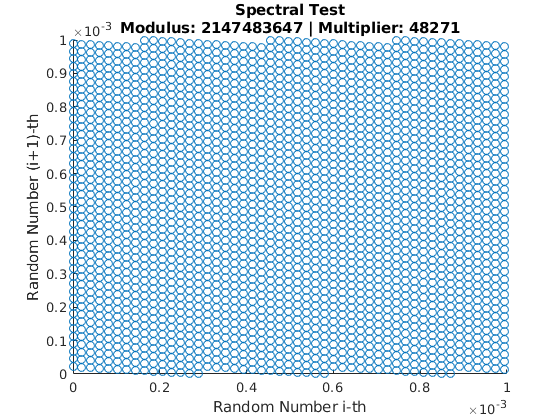

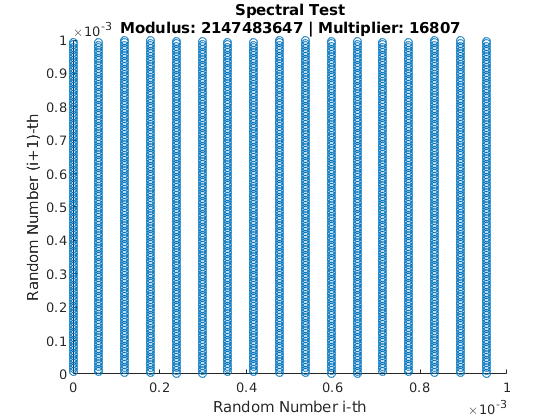

for multiplier = multipliers
    data = readtable(sprintf("random/out/spectral/mod%d_mul%d.csv", modulus, multiplier));
    
    x = data.u1;
    y = data.u2;
    
    scatter(x, y);
    title({"Spectral Test";sprintf("Modulus: %d | Multiplier: %d", modulus, multiplier)});
    xlabel("Random Number i-th");
    ylabel("Random Number (i+1)-th");
    figure;
end

`Test of Extremes`

`Let us see the results obtained with the Test of Extremes.`

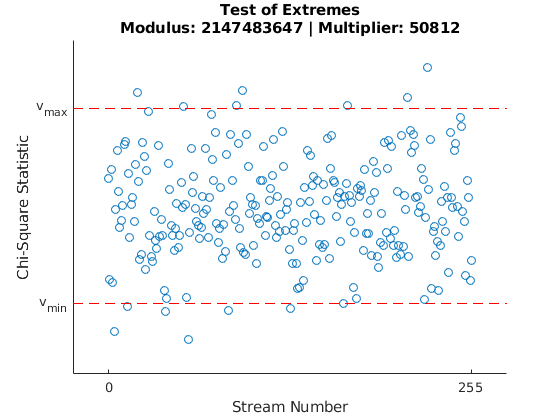

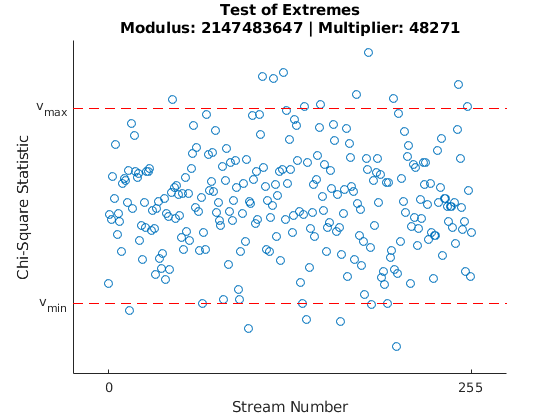

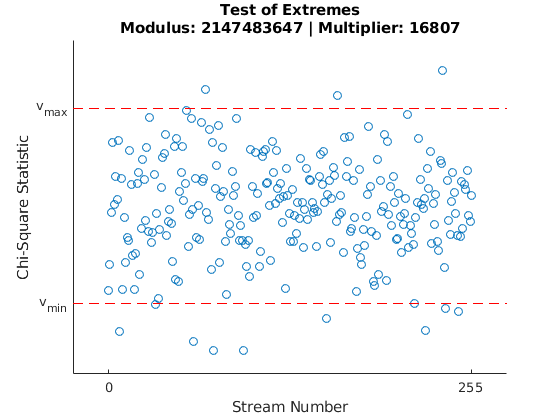

for multiplier = multipliers
    data = readtable(sprintf('random/out/extremes/mod%d_mul%d.csv', modulus, multiplier));
    report = readtable(sprintf('random/out/extremes/mod%d_mul%d_report.csv', modulus, multiplier));
    
    x = data.stream;
    y = data.value;
    
    criticalLower = report.critical_bounds_lower_bound;
    criticalUpper = report.critical_bounds_upper_bound;
    
    streams = length(x);
    offset = 25;
    
    scatter(x, y);
    hold on
    plot([-offset streams-1+offset], [1 1] * criticalLower, '--r')
    plot([-offset streams-1+offset], [1 1] * criticalUpper, '--r')
    hold off
    title({'Test of Extremes';sprintf('Modulus: %d | Multiplier: %d', modulus, multiplier)});
    xlabel('Stream Number');
    ylabel('Chi-Square Statistic');
    xlim([ -offset streams-1+offset ])
    set(gca,'xtick',[0 streams-1]);
    set(gca,'ytick',[criticalLower criticalUpper]);
    yticklabels({'v_{min}', 'v_{max}'});
    figure;
end

`Kolmogorov-Smirnov Analysis`

`Let us see the results obtained with the Kolmogorov-Smirnov Analysis.`

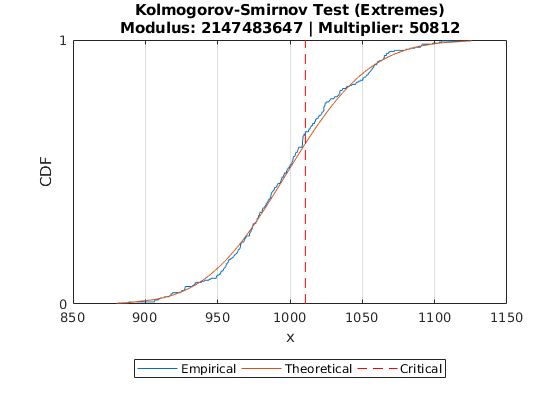

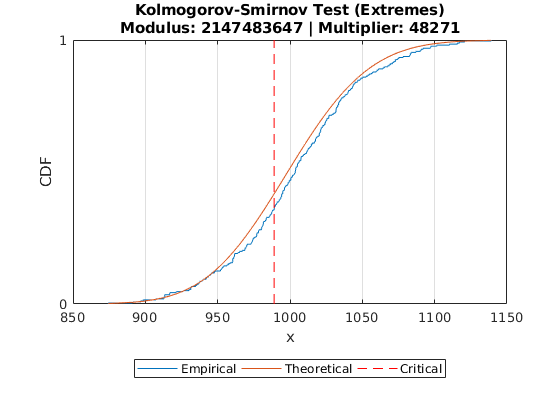

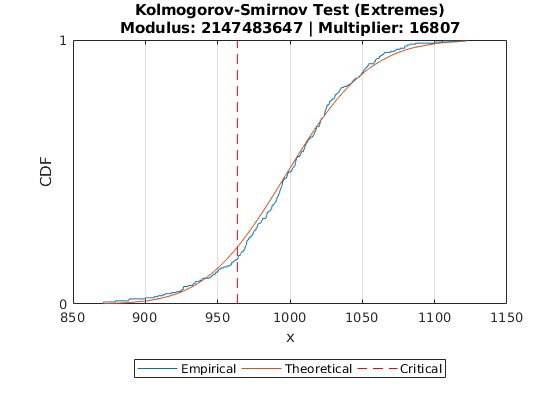

for multiplier = multipliers
    data = readtable(sprintf('random/out/kolmogorov-smirnov/extremes/mod%d_mul%d.csv', modulus, multiplier));
    report = readtable(sprintf('random/out/kolmogorov-smirnov/extremes/mod%d_mul%d_report.csv', modulus, multiplier));
    
    bins = report.test_parameters_bins;
    critical = report.ks_ks_point_x;
    
    empirical = sort(data.value);
    theoretical = chi2cdf(empirical, bins - 1);
    
    cdfplot(empirical)
    hold on
    plot(empirical, theoretical)
    plot([1 1] * critical, [0.0 1.0], '--r')
    hold off
    title({'Kolmogorov-Smirnov Test (Extremes)';sprintf('Modulus: %d | Multiplier: %d', modulus, multiplier)});
    xlabel('x');
    ylabel('CDF');
    set(gca,'ytick',[0.0 1.0]);
    legend('Empirical', 'Theoretical', 'Critical', 'Location', 'southoutside', 'Orientation', 'horizontal');
    figure;
end

## `Transient Analysis`

`Let us now study the transient period of the simulated system.`

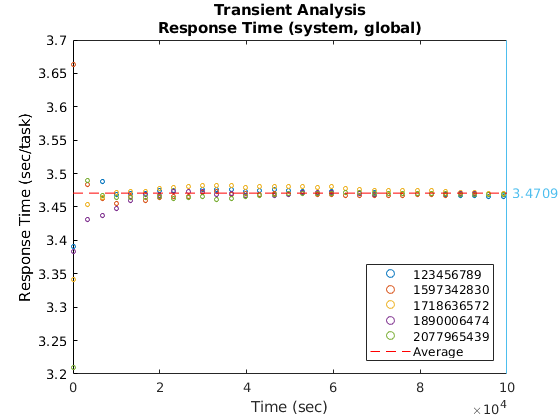

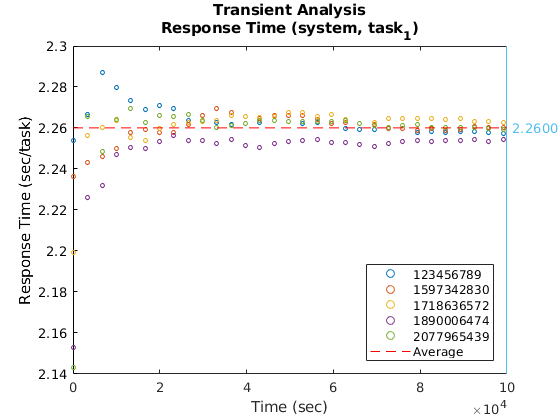

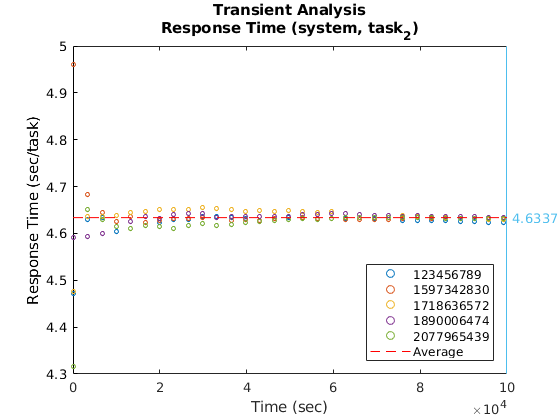

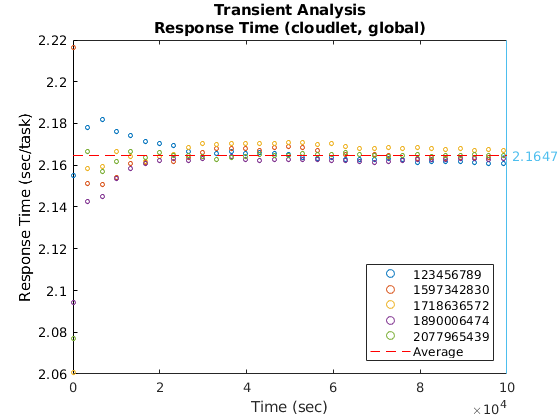

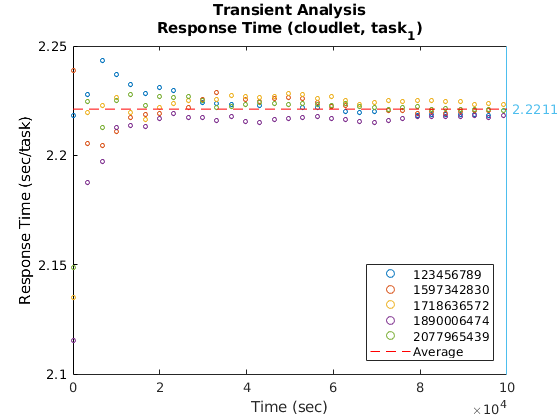

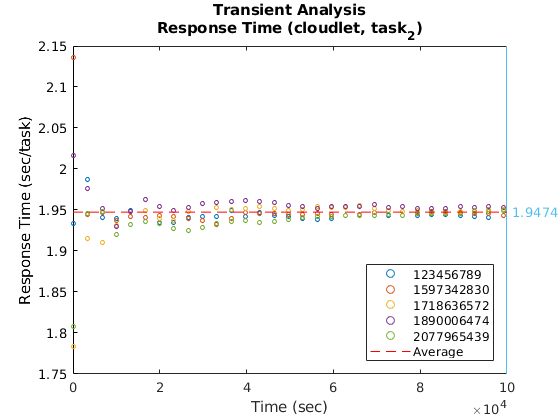

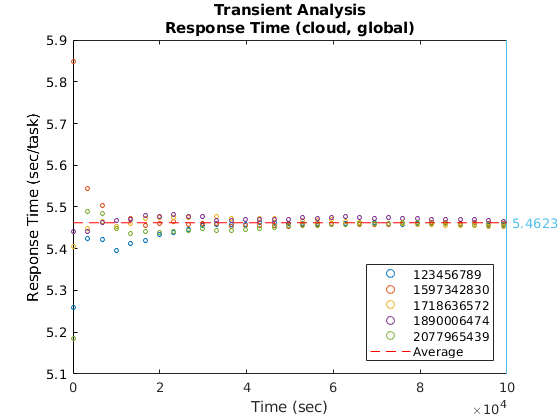

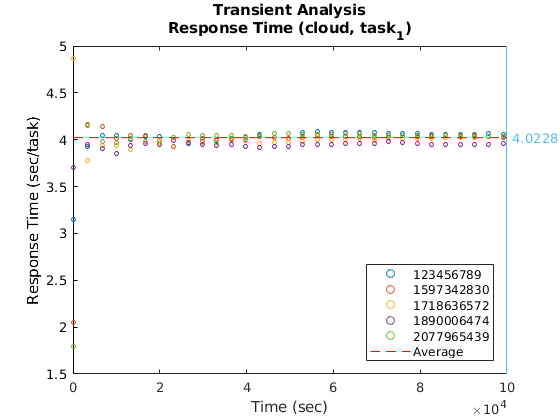

metrics   = ["response", "throughput", "population", "switched_ratio", "switched_response"];
sysScopes = ["system", "cloudlet", "cloud"];
tskScopes = ["global", "task_1", "task_2"];
units     = ["sec/task", "task/sec", "task", "ratio", "sec/task"];
headings  = ["Response Time", "Throughput", "Mean Population", "Switched Ratio", "Switched Response Time"];

samplePoints = 30;
ratioForMean = 0.5;

ls = dir('simulation/out/transient_analysis/seed_*');
seeds = strrep(string({ls.name}.'),'seed_','');

for m = 1:length(metrics)
    for s = 1:length(sysScopes)
        for t = 1:length(tskScopes)
            metric = metrics(m);
            sys    = sysScopes(s);
            tsk    = tskScopes(t);
            unit   = units(m);
            
            heading = sprintf("%s (%s, %s)", headings(m), sys, tsk);
            entry   = sprintf("%s_%s_%s", metric, sys, tsk);    
            
            valuesForMean = [];
            
            title({'Transient Analysis', heading});
            xlabel('Time (sec)');
            ylabel(sprintf('%s (%s)', headings(m), unit));
            
            hold on
            
            for sd = 1:length(seeds)
                seed = seeds{sd,1};
                data = readtable(sprintf('simulation/out/transient_analysis/seed_%s/result.sampling.csv', seed));
                time = data.time;
                values = data.(char(entry));
                
                nValues = length(time);
                valuesForMean = cat(1, valuesForMean, values(floor(ratioForMean*nValues):1:end));        
                samplePace = floor(nValues/samplePoints);
            
                scatter(time(1:samplePace:end), values(1:samplePace:end), 10, 'LineWidth', 0.1, 'DisplayName', seed);    
            end
            
            hold off
            
            xl = xlim;
            yl = ylim;            
            
            avg = mean(valuesForMean);
            
            yyaxis right
            plot(xl, [avg avg], '--r', 'DisplayName', 'Average');
            ylim(yl);
            set(gca,'ytick', (avg));
            legend('show', 'Location', 'southeast', 'Orientation', 'vertical');
            figure;
        end
    end    
end

## `Performance Evaluation`

`Let us now visualize how performance metrics behave in response to threhsold variations.`

%metrics   = ["response", "throughput", "population", "switched_ratio", "switched_response"];
%sysScopes = ["system", "cloudlet", "cloud"];
%tskScopes = ["global", "task_1", "task_2"];
%units     = ["sec/task", "task/sec", "task", "ratio", "sec/task"];
%headings  = ["Response Time", "Throughput", "Mean Population", "Switched Ratio", "Switched Response Time"];

%data = readtable('simulation/out/performance_analysis/result.csv');

%thresholds = data.system_cloudlet_threshold;

%one = ones(size(thresholds));
%for m = 1:length(metrics)
%    for s = 1:length(sysScopes)
%        for t = 1:length(tskScopes)
%            metric = metrics(m);
%            sys = sysScopes(s);
%            tsk = tskScopes(t);
%            unit    = units(m);
%            
%            heading = sprintf("%s (%s, %s)", headings(m), sys, tsk);
%            ventry  = sprintf("statistics_%s_%s_%s_mean", metric, sys, tsk);
%            eentry  = sprintf("statistics_%s_%s_%s_cint", metric, sys, tsk);            
%            
%            values = data.(char(ventry));
%            errors = data.(char(eentry));
%            
%            mn = min(values);
%            mx = max(values);
%            
%            errorbar(thresholds, values, errors, 'DisplayName', 'Mean');
%            title({'Performance Analysis', heading});
%            xlabel('Cloudlet Threshold (task)');
%            ylabel(sprintf('%s (%s)', headings(m), unit));
%            
%            yl = ylim;
%            
%            yyaxis right
%            hold on
%            plot(thresholds, ones(size(thresholds)) * mn, '--r', 'DisplayName', 'Minimum');
%            plot(thresholds, ones(size(thresholds)) * mx, '--r', 'DisplayName', 'Maximum');
%            hold off
%            ylim(yl);
%            if mn ~= mx
%                set(gca,'ytick', [mn, mx]);
%            else
%                set(gca,'ytick', (mn));
%            end
%            legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');
%            figure;
%        end
%    end
%end

`Let us now summarize the resulting metrics in a tabular fashion.`

%tabularFields  = repmat("", length(metrics)+1, 1);
%tabularEntries = repmat("", length(metrics)+1, 1);
%
%tabularFields(1) = "threshold";
%tabularEntries(1) = "system_cloudlet_threshold";
%
%tblIdx = 2;
%for m = 1:length(metrics)
%    for s = 1:length(sysScopes)
%        for t = 1:length(tskScopes)
%            metric = metrics(m);
%            sys = sysScopes(s);
%            tsk = tskScopes(t);
%            tabularFields(tblIdx)  = sprintf("%s_%s_%s", metric, sys, tsk);
%            tabularEntries(tblIdx) = sprintf("statistics_%s_%s_%s_mean", metric, sys, tsk);
%            tblIdx = tblIdx + 1;
%        end
%    end
%end
%
%tabular = data(:,cellstr(tabularEntries));
%tabular.Properties.VariableNames = cellstr(tabularFields);
%disp(tabular);

## `Distribution Analysis`

`Let us now study the probability distribution function and the cumulative distribution function of a given metric. Please, notice that the variable ``dists`` should be modified accordingly to the result reported by the Distribution Fitter.`

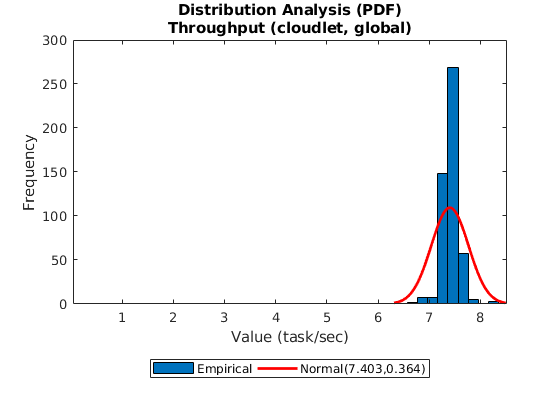

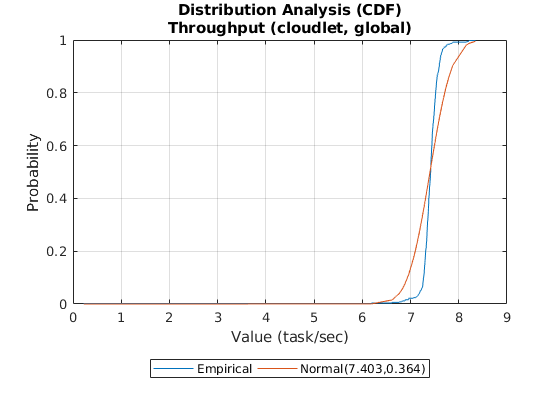

metrics   = ["throughput"];%["response", "throughput", "population"];
sysScopes = ["cloudlet"];%["system", "cloudlet", "cloud"];
tskScopes = ["global"];%["global", "task_1", "task_2"];
units     = ["task/sec"];%["sec/task", "task/sec", "task"];
headings  = ["Throughput"];%["Response Time", "Throughput", "Mean Population"];
%dists    = ["GeneralizedExtremeValue", "GeneralizedExtremeValue", "GeneralizedExtremeValue"];
dists     = ["Normal"];%["Normal", "Normal", "Normal"];

S = 20;

data = readtable(sprintf('simulation/out/performance_analysis/%d/result.sampling.csv', S));

for m = 1:length(metrics)
    for s = 1:length(sysScopes)
        for t = 1:length(tskScopes)
            metric = metrics(m);
            unit = units(m);
            dist = dists(m);
            sys = sysScopes(s);
            tsk = tskScopes(t);
            
            heading = sprintf("%s (%s, %s)", headings(m), sys, tsk);
            entry = sprintf("%s_%s_%s", metric, sys, tsk);
            
            empirical = sort(data.(char(entry)));
            
            %%
            % PDF
            %%
            bins = size(histcounts(empirical), 2);
            dparams = fitdist(empirical, char(dist));
            histfit(empirical, bins, char(dist));
            title({'Distribution Analysis (PDF)', heading});
            xlabel(sprintf('Value (%s)', unit));
            ylabel('Frequency');
            %legend('Empirical', sprintf("%s(%.3f,%.3f,%.3f)", dist, dparams.k, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
            legend('Empirical', sprintf("%s(%.3f,%.3f)", dist, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
            figure;
            
            %%
            % CDF
            %%
            cdfplot(empirical);
            %cdfTheoretical = cdf(char(dist), empirical, dparams.k, dparams.sigma, dparams.mu);
            cdfTheoretical = cdf(char(dist), empirical, dparams.mu, dparams.sigma);
            hold on
            plot(empirical, cdfTheoretical);
            hold off
            
            title({'Distribution Analysis (CDF)', heading});
            xlabel(sprintf('Value (%s)', unit));
            ylabel('Probability');
            %legend('Empirical', sprintf("%s(%.3f,%.3f,%.3f)", dist, dparams.k, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
            legend('Empirical', sprintf("%s(%.3f,%.3f)", dist, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
            figure;
        end
    end
end

## `Verification`

`Let us now verify the correctness of the experimental model by comparing the computed experimental results with the expected theoretical ones.`

`To this aim, we leverage the Markov Chain modeling of the system so to use the calculated steady-state probabilities to compare experimental performance indeces with the theoretical ones.`

config = readtable('verification/out/markov_analysis/config.csv');
data = readtable('verification/out/markov_analysis/transition_matrix.csv');
states = readtable('verification/out/markov_analysis/states.csv');
states_clt_1 = readtable('verification/out/markov_analysis/states_clt_1.csv');
states_clt_2 = readtable('verification/out/markov_analysis/states_clt_2.csv');
states_clt_3 = readtable('verification/out/markov_analysis/states_clt_3.csv');

% Configuration
arrival_1 = config.arrival_1;
arrival_2 = config.arrival_2;
clt_service_1 = config.clt_service_1;
clt_service_2 = config.clt_service_2;
cld_service_1 = config.cld_service_1;
cld_service_2 = config.cld_service_2;
T_setup = config.t_setup;
psi = 1/2;

% State Probabilities

transitionMatrix = data{:,:};
[V,D] = eig(transitionMatrix');
P = V(:,1)';P = P./sum(P);
P_Table = array2table(P, 'VariableNames', table2cell(states));
disp(P_Table);

      A0A0        A0A1        A0A2       A1A0       A1A1       A2A0  
    ________    ________    ________    _______    _______    _______

    0.013284    0.048591    0.060993    0.11783    0.27996    0.47934




p_states_clt_1 = P_Table{1,table2cell(states_clt_1(:,1))};
p_states_clt_2 = P_Table{1,table2cell(states_clt_2(:,1))};
p_states_clt_3 = P_Table{1,table2cell(states_clt_3(:,1))};

% Routing Probabilities
a_clt_1 = sum(p_states_clt_1);
a_clt_2 = sum(p_states_clt_2);
r = sum(p_states_clt_3) * (arrival_1/(arrival_1+arrival_2));

disp('ROUTING PROBABILITIES');

ROUTING PROBABILITIES


fprintf('a_clt_1: %f', a_clt_1);

a_clt_1: 0.520656

fprintf('a_clt_2: %f', a_clt_2);

a_clt_2: 0.179707

fprintf('r: %f', r);

r: 0.166996


% Accepted Traffic
lambda_clt_1 = a_clt_1 * arrival_1;
lambda_clt_2 = a_clt_2 * arrival_2;
lambda_cld_1 = (1-a_clt_1) * arrival_1;
lambda_cld_2 = (1-a_clt_2) * arrival_2;

disp('ACCEPTED TRAFFIC');

ACCEPTED TRAFFIC


fprintf('lambda_clt_1: %f', lambda_clt_1);

lambda_clt_1: 3.123938

fprintf('lambda_clt_2: %f', lambda_clt_2);

lambda_clt_2: 1.123166

fprintf('lambda_cld_1: %f', lambda_cld_1);

lambda_cld_1: 2.876062

fprintf('lambda_cld_2: %f', lambda_cld_2);

lambda_cld_2: 5.126834


% Preempted Traffic
lambda_p = r * (arrival_1+arrival_2);

disp('PREEMPTED TRAFFIC');

PREEMPTED TRAFFIC


fprintf('lambda_p: %f', lambda_p);

lambda_p: 2.045698


% Performance Metrics: Cloudlet
T_clt_1 = 1 / clt_service_1;
N_clt_1 = lambda_clt_1 * T_clt_1;
T_clt_2 = 1 / clt_service_2;
N_clt_2 = (lambda_clt_2 * T_clt_2) - (psi * lambda_p * T_clt_2);
N_clt = N_clt_1 + N_clt_2;
T_clt = ((N_clt_1/N_clt) * T_clt_1) + ((N_clt_2/N_clt) * T_clt_2);
X_clt_1 = lambda_clt_1;
X_clt_2 = lambda_clt_2 - lambda_p;
X_clt = lambda_clt_1 + lambda_clt_2 - lambda_p;

disp('PERFORMANCE METRICS: CLOUDLET');

PERFORMANCE METRICS: CLOUDLET


fprintf('T_clt_1: %f', T_clt_1);

T_clt_1: 2.222222

fprintf('N_clt_1: %f', N_clt_1);

N_clt_1: 6.942085

fprintf('T_clt_2: %f', T_clt_2);

T_clt_2: 3.703704

fprintf('N_clt_2: %f', N_clt_2);

N_clt_2: 0.371545

fprintf('N_clt: %f', N_clt);

N_clt: 7.313630

fprintf('T_clt: %f', T_clt);

T_clt: 2.297484

fprintf('X_clt_1: %f', X_clt_1);

X_clt_1: 3.123938

fprintf('X_clt_2: %f', X_clt_2);

X_clt_2: -0.922532

fprintf('X_clt: %f', X_clt);

X_clt: 2.201406


% Performance Metrics: Cloud
T_cld_1 = 1 / cld_service_1;
N_cld_1 = lambda_cld_1 * T_cld_1;
T_cld_2_np = 1 / cld_service_2;
N_cld_2_np = lambda_cld_2 * T_cld_2_np;
T_cld_2_p = T_cld_2_np + T_setup + (psi * T_clt_2);
N_cld_2_p = lambda_p * T_cld_2_p;
N_cld_2 = N_cld_2_np + N_cld_2_p;
T_cld_2 = ((N_cld_2_np/N_cld_2) * T_cld_2_np) + ((N_cld_2_p/N_cld_2) * T_cld_2_p);
N_cld = N_cld_1 + N_cld_2;
T_cld = ((N_cld_1/N_cld) * T_cld_1) + ((N_cld_2/N_cld) * T_cld_2);
X_cld_1 = lambda_cld_1;
X_cld_2 = lambda_cld_2 + lambda_p;
X_cld = lambda_cld_1 + lambda_cld_2 + lambda_p;

disp('PERFORMANCE METRICS: CLOUD');

PERFORMANCE METRICS: CLOUD


fprintf('T_cld_1: %f', T_cld_1);

T_cld_1: 4.000000

fprintf('N_cld_1: %f', N_cld_1);

N_cld_1: 11.504248

fprintf('T_cld_2_np: %f', T_cld_2_np);

T_cld_2_np: 4.545455

fprintf('N_cld_2_np: %f', N_cld_2_np);

N_cld_2_np: 23.303789

fprintf('T_cld_2_p: %f', T_cld_2_p);

T_cld_2_p: 7.197306

fprintf('N_cld_2_p: %f', N_cld_2_p);

N_cld_2_p: 14.723518

fprintf('N_cld_2: %f', N_cld_2);

N_cld_2: 38.027307

fprintf('T_cld_2: %f', T_cld_2);

T_cld_2: 5.572206

fprintf('N_cld: %f', N_cld);

N_cld: 49.531555

fprintf('T_cld: %f', T_cld);

T_cld: 5.207044

fprintf('X_cld_1: %f', X_cld_1);

X_cld_1: 2.876062

fprintf('X_cld_2: %f', X_cld_2);

X_cld_2: 7.172532

fprintf('X_cld: %f', X_cld);

X_cld: 10.048594


% Performance Metrics: System
N_sys = N_clt + N_cld;
T_sys = ((N_clt / N_sys) * T_clt) + ((N_cld/N_sys) * T_cld);
X_sys = X_clt + X_cld;

disp('PERFORMANCE METRICS: SYSTEM');

PERFORMANCE METRICS: SYSTEM


fprintf('N_sys: %f', N_sys);

N_sys: 56.845185

fprintf('T_sys: %f', T_sys);

T_sys: 4.832704

fprintf('X_sys: %f', X_sys);

X_sys: 12.250000

## `bla bla bla`

lambda_1 = 4;
lambda_2 = 6.25;
mu_cld_1 = 0.45;
mu_cld_2 = 0.27;

syms p00 p01 p02 p10 p11 p20;
eqn1 = p00*(lambda_1+lambda_2) == p10*mu_cld_1+p01*mu_cld_2;
eqn2 = p01*(lambda_1+lambda_2+mu_cld_2) == p00*lambda_2+p11*mu_cld_1+p02*2*mu_cld_2;
eqn3 = p10*(lambda_1+lambda_2+mu_cld_1) == p00*lambda_1+p11*mu_cld_2+p20*2*mu_cld_1;
eqn4 = p11*(lambda_1+mu_cld_1+mu_cld_2) == p01*lambda_1+p10*lambda_2+p02*lambda_1;
eqn5 = p02*(lambda_1+2*mu_cld_2) == p01*lambda_2;
eqn6 = p20*2*mu_cld_1 == p10*lambda_1+p11*lambda_1;
eqn7 = p00+p01+p02+p10+p11+p20 == 1;

sol = solve([eqn1, eqn2, eqn3, eqn4, eqn5, eqn6, eqn7], [p00,p01,p02,p10,p11,p20], 'Real', true);

## `References`

- `Relazione, `[`https://www.cryptocompare.com`](https://www.cryptocompare.com)

- `Repo Github, `[`https://www.github.com/gmarciani/pydes`](https://www.cryptocompare.com)

- `Performance Modeling of Computer Systems and Networks, `[`http://didattica.uniroma2.it/informazioni/index/insegnamento/172514-Performance-Modeling-Of-Computer-Systems-And-Networks`](http://didattica.uniroma2.it/informazioni/index/insegnamento/172514-Performance-Modeling-Of-Computer-Systems-And-Networks)

- `Leemis, Lawrence M., and Stephen Keith Park. ``Discrete-event simulation: A first course``. Upper Saddle River, NJ: Pearson Prentice Hall, 2006.`

- `Harchol-Balter, Mor. ``Performance modeling and design of computer systems: queueing theory in action``. Cambridge University Press, 2013.`